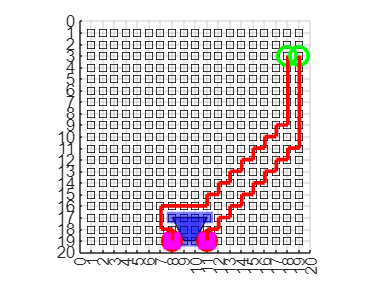

Final first point is reached


Final second point is reached
Visit list:


Second point is reached
First point is reached


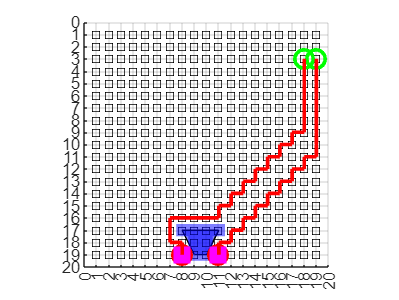

% The obstacle is defined in the path1_finder function
% The map is defined also in the path1_finder function

n = 20; % Represents the grid size

%%Initial points
xi1 = 3; % Represents matrix raws
yi1 = 18; % Represents matrix columns
xi2 = 3 ;% Represents matrix raws
yi2 = 19;% Represents matrix columns

%%Final points
xf1 = 8; % Represents an x-axis from left to right
yf1 = n-1; % Represents an y-axis top to bottom
xf2 = 11;% Represents an x-axis from left to right
yf2 = n-1;% Represents an y-axis top to bottom

A = map_and_obstacle(n,xf1,yf1,xf2,yf2);

% Choosing the closer final point for each starting point
% The object is on the table so we assume that the gripper always start in the same height (yi1 >/< yi2)
% Left finger of the gripper goes to the left gripping point 
% Right finger of the gripper goes to the Right gripping point 
if (yi1-xf1) < (yi2-xf1)
    [visited_first_path,matrix_A] = path1_finder(xi1,yi1,xf1,yf1,A);
    [visited_second_path] = path2_finder(xi2,yi2,xf2,yf2,matrix_A,visited_first_path);
    chosen_paths_map(visited_first_path,visited_second_path,n);
else
    [visited_first_path,matrix_A] = path1_finder(xi2,yi2,xf1,yf1,A);
    [visited_second_path] = path2_finder(xi1,yi1,xf2,yf2,matrix_A,visited_first_path);
    chosen_paths_map(visited_first_path,visited_second_path,n);

end